# Getting started -----------------------------------------------------------------------------------------------------------

## Stability selection overview

StabSel performs stability selection, retrieving a set of features from your data in X that are more consistently predictive of your response variable y across many different perturbed versions of X (a future update will work with classification problems). You can use stabSel to determine which variables predict y using something simple, like correlation, or using something more complex, like an adaptive elastic net or a random forest. Either way, the strength of stabSel is that it selects a set of features that best predict y in a more generalizable and precise way than possible when running your feature selection method just once on your entire dataset. In addition, stability selection lets us control the number of false positives in the set of features we deem to be important (also sometimes referred to as "stable" or "consistent" features). This is nice because while stabSel was created to generally facilitate reducing the number of features that would enter a predictive model, it also allows us to directly discover features that significantly predict our response variable, letting us assign p-values to associations between the response variable and our features that were mapped using algorithms that don't traditionally allow us to do this kind of statistical testing. For example, this lets us assign p-values to features discovered to be important using out-of-bag error in a random forest, which can detect both nonlinear and linear relationships. 

The documentation in stabSel can give you a better sense of what it can do--there are lots of bells and whistles, and arguably lots of options you can set that 99% of users would never care about (and which should not make much difference to the results). Like any method, stability selection is not a panacea so please keep in mind that it is not guaranteed to improve your results. For example, it *can* be easy to overfit your data if you do not have many samples and the relationships in the data happen to be very complex, leaving you with a set of "stable" features identified in a training dataset that would have never been selected if the test data were used instead. This is not to say that stability selection does not improve models when sample sizes are low, but that there is no guarantee of improvement.

## Getting started with some toy data

Below are some examples showing you how to use stabSel. I've uploaded a toy dataset for us to work with here: [https://drive.google.com/file/d/1nUSnseZHNdpDG-UXGhFNvZNaydlLg3LN/view?usp=sharing](https://drive.google.com/file/d/1nUSnseZHNdpDG-UXGhFNvZNaydlLg3LN/view?usp=sharing)

First, download that dataset and copy it into the folder that contains the StabilitySelection repository:

copyfile('~/Downloads/stabSelToy.mat','~/Downloads/StabilitySelection-main/') % you may have to change this to whatever folder contains stabSel)

Now let's navigate to the directory that contains StabilitySelection (e.g., cd('~/Downloads/StabilitySelection-main/')) and load up the toy dataset.

cd('~/Downloads/StabilitySelection-main/') % you may have to change this to whatever folder contains stabSel
clear; load stabSelToy

As a disclaimer, this dataset was selected quasi-randomly from the UCI machine learning repository. The variables are very strongly intercorrelated, which is not ideal for showing how effective stabSel can be (it shines when there are many noisy features). In any case, the examples show you how to use stabSel and help demonstrate its value.

Once you've loaded in the dataset, you should see an X and y variable in the workspace. X contains a subset of the million song database. Every row in X is a different song, and every column is a feature related to timbre (e.g., covariance). We would like to know if we can use information about timbre to predict the year in which a song was produced. Song years are stored in a single column in y. For the purposes of these example analyses, we don't care about precisely interpreting our features. If you want to know more about the dataset we'll be using, you can find more info here: [http://archive.ics.uci.edu/ml/datasets/YearPredictionMSD#](http://archive.ics.uci.edu/ml/datasets/YearPredictionMSD#)

When using stabSel on your own data, make sure that features are stored in the columns of X, and that rows of X and y correspond to samples (y should have 1 single column). The minimum input variables stabSel needs to function are X and y. For example, you can run stabSel just like this:

%[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(X,y);

However, the code above might not give you the results you are looking for as it will apply a very stringent threshold to the feature selection process (as the examples below illustrate in more detail).

# Example 1: Reducing the feature set when building a predictive model ------------------------------------------------------------------

This is the example that stabSel was initially written in mind with. Let's say we want to build a model to predict song year, but we have much too many features than we can work with--maybe thousands. If the samples in our model approach or exceed the number of features that we have, then our model would likely benefit from feature reduction.

If our goal is to simply reduce feature size and not to precisely define the measured properties of timbre that significantly predict song year, then we can use stabSel in a relatively blunt way. This is what we will do in this example, folding stability selection into a cross-validation scheme for testing the ability of a linear regression model to predict song year. 

## Basic resampling, feature selection, and probability threshold options in stabSel

The core idea in stability selection is to resample your data many times, each time forcing a feature selection method to select some number of most important features for predicting y. Looking over these many resampled datasets, we can then compute the probability that a feature was selected. If the probability is high enough, we then add that feature to a set of "stable" features that are more consistently selected across perturbed versions of our dataset. Typically, we resample 50% of the dataset, but in some cases it may make sense to resample more or less of the data. For example, in the case that sample size is very small, resampling more of the data can improve stability selection but may upset the equations that we use for correcting false positives in our stable set (more on that later). To change any option in stabSel, like the proportion of data resampled, we add that option to our call to stabSel, like so: 

%[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(trX,trY,'samType','bootstrap');

The initial paper to propose stability selection advocated for sampling without replacement. Some folks since then have advocated for sampling with replacement, although these two options are effectively interchangeable for certain resampling proportions (see stabSel.m). We can also create complementary pairs of samples to reduce the number of resamples that we need to take in order to get a good estimate of feature selection probability. However, keep in mind that this is mostly advocated for in the context of sampling with replacement.

#### Setting up our options for stabSel

In this example, we'll stick with the resampling technique from the original stability selection proposal: subsampling without taking complementary pairs of subsamples (controlled by 'samType' option). We'll repeat our subsampling procedure only 50 times to keep the analysis quick (controlled by 'prop'), but you should increase this number to something more reasonable when analyzing your own data (e.g., 500). For selecting our features, we will use a very simple and fast method: correlation (controlled by 'selAlgo' option). This means that in each subsample, we will correlate the response variable with each feature. We will then force the selection method to remove ~80% of our features (controlled by 'maxVars' option). We will deem any feature that is selected in at least half of the subsamples as 'stable'. A lower threshold here makes some sense given that it will be hard for correlation to rank our features well (i.e., they're all strongly intercorrelated and so less likely to be consistently selected across subsamples). 

#### Setting up a cross-validation scheme 

In this example, we want to know how well our model predicts our response variable. Let's set up an 8-fold CV scheme, which will allow us to evaluate the model we train on data that it has not seen, giving us a more realistic estimate of its performance. We will also fix the random number generator so that the results of this example are a bit more replicable. Your results will still vary, however. There are lots of stochastic elements involved. 

rng('default'); rng(1); % here we initialize a repeatable number generator with a seed of 1
c = cvpartition(length(y),'Kfold',8); % this is a structure that contains our folds

## Testing stabSel model using out of sample data

Now we will loop through our test folds. For each fold, we will find all of the samples of our data that were *not* in the fold and use those samples to train two linear regression models. One model will be trained on all of the features stored in X. A second model will be trained on features selected by stabSel. Our goal will be to test whether reducing our feature set with stabSel wil improve performance of the model on data it has never seen.

for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run stability selection
    [fk,~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'thresh',0.5,...
        'maxVars',round(size(trX,2)/6)); 
    % We use 'filter' in the call because correlation can be used as either
    % a filter for ranking variables, or to select significant variables on
    % each resample (by default stabSel has filter set to false because the
    % default selection algorithm does not make sense to use as a filter).

    % Train/test models
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train stabSel augmented model using ridge regression
    yhat(test(c,i),1) = predict(mdl,teX(:,fk)); % test this model
    mdl = fitrlinear(trX,trY,'Learner','leastsquares'); % repeat processs without stabSel (ridge regression)
    yhat2(test(c,i),1) = predict(mdl,teX);
end

Working on test set 1 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 15
Effective per-comparison rate p-value is: 0.011111


Working on test set 2 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 14
Effective per-comparison rate p-value is: 0.011111


Working on test set 3 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 14
Effective per-comparison rate p-value is: 0.011111


Working on test set 4 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 14
Effective per-comparison rate p-value is: 0.011111


Working on test set 5 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 14
Effective per-comparison rate p-value is: 0.011111


Working on test set 6 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 14
Effective per-comparison rate p-value is: 0.011111


Working on test set 7 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 14
Effective per-comparison rate p-value is: 0.011111


Working on test set 8 of 8


Effective FDR-like p-value is: Inf. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 15
Effective per-comparison rate p-value is: 0.011111


% evaluate performance
r1 = corr(y,yhat) % stabSel model

r1 = 0.1311

r2 = corr(y,yhat2) % model trained using all features

r2 = 0.1090

mse1 = mean((y-yhat).^2)

mse1 = 112.1226

mse2 = mean((y-yhat2).^2)

mse2 = 113.1402

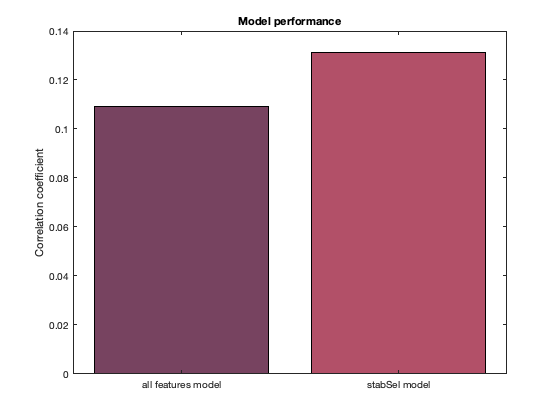

% Create barcharts for performance
b=bar(categorical({'stabSel model','all features model'}),[r1 r2],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(2,:) = ([178 80 104])/255;
title('Model performance')
ylabel('Correlation coefficient')

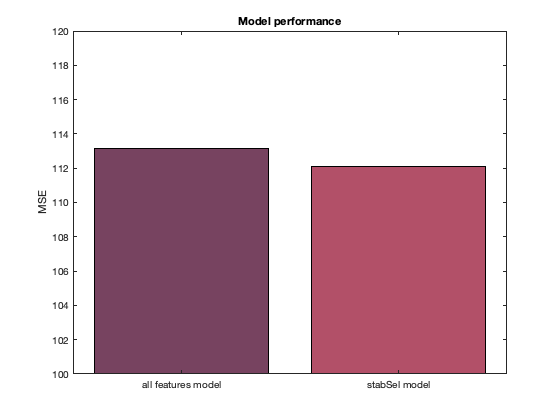

b=bar(categorical({'stabSel model','all features model'}),[mse1 mse2],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(2,:) = ([178 80 104])/255;
ylim([100 120])
title('Model performance')
ylabel('MSE')

How did the models do for you? On my end, the stabSel model's performance as measured by correlating predictions of song year with actual song year (in r1) was 0.1368. The model that used all features got an r-value of 0.109. This was consistent across ~20 repeats of the code above with shuffled rng so you should have also found better performance for the stabSel model (also true of mean squared error as stored in mse1 and mse1).  

You may have noticed stabSel displayed some other data each time it ran. For example, our effective FWER p-value was Inf! That's okay as we were not attempting to put a p-value on our selected features. We can also see that the number of features that were in the stable set were ~15. That means that even though we forced the correlation method to select 15 features in each subsample, our probability threshold for the stable set ended up giving us 15 features in the stable set too. 

Unfortunately, these results also tell us that clearly we cannot predict song year from timbre very well using our linear regression model. Nevertheless, you can see that reducing our feature set helped us net a small increase in performance. But how would the model have done if we had run a simple correlation filter without stability selection?

for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run correlation filter -- this is how correlation would be
    % used inside a subsample in stabSel as called in the last block of
    % code
    rtmp = corr(trX,trY);
    [~,idx] = sort(rtmp,'descend');
    fk = idx(1:15); % this is rought the number of features stability selection selected for us on each fold

    % Train/test models
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train filter augmented model
    yhat3(test(c,i),1) = predict(mdl,teX(:,fk)); % test this model
end

Working on test set 1 of 8
Working on test set 2 of 8
Working on test set 3 of 8
Working on test set 4 of 8
Working on test set 5 of 8
Working on test set 6 of 8
Working on test set 7 of 8
Working on test set 8 of 8


% evaluate performance
r3 = corr(y,yhat3) % filter model

r3 = 0.0990

mse3 = mean((y-yhat3).^2)

mse3 = 113.4743

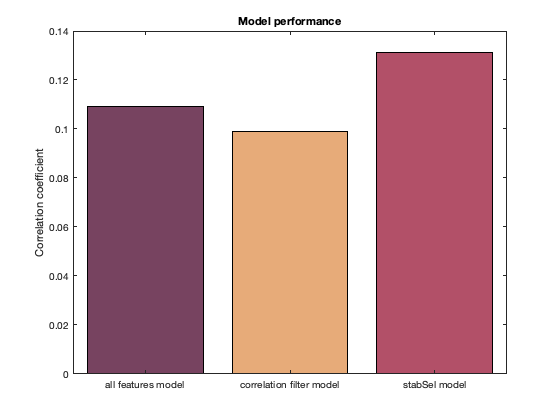

% Create barcharts for performance
b=bar(categorical({'all features model','correlation filter model','stabSel model'}),[r2 r3 r1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(3,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
title('Model performance')
ylabel('Correlation coefficient')

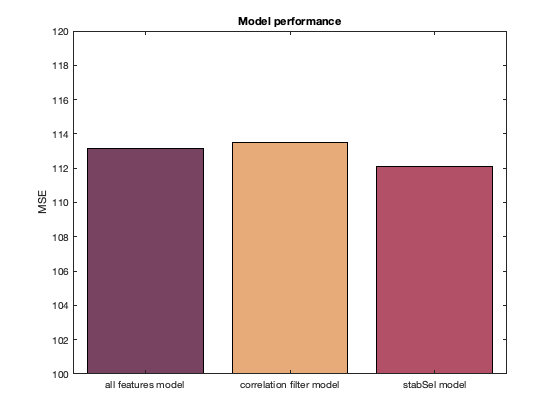

b=bar(categorical({'all features model','correlation filter model','stabSel model'}),[mse2 mse3 mse1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(3,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
ylim([100 120])
title('Model performance')
ylabel('MSE')

As you can probably see, repeating the filtering process over slightly different subsets of your data performs *much* better, helping to select features in a way that is less likely to lead to overfitting. In my case, r3 was 0.0986 for the model above (and mse2 was also much lower than mse3). Stability selection works!

I will end this example on one final point to help you use stabSel in the way we have above. In this example, we have selected some options in stabSel (e.g., 'thresh', 'maxVars') based on the qualities of our data, but also in some arbitrary ways. Exactly how much you want to shrink your feature space is a subjective question that can be controlled by manipulating *both* thresh and maxVars. If I want stabSel to return exactly 15 features in the stable set, I can either choose an arbitrary maxVars and dial in the threshold until I get to that many features, or I can go in the other direction and choose an arbitrary threshold and dial in maxVars. The angle this problem is approached from shouldn't really matter. In fact, for stability selection with lasso, changing 'thresh' at all has been suggested not to influence the results very much (at least when maxVars is estimated to ensure <1 false positive as discussed in the next example). Lastly, I want to mention you probably shouldn't be using correlation as your feature selection method:) It sure is fast, but stabSel can do a lot more.

# Example 2: Discovering features that predict the response variable ----------------------------------------------------------------------

## Controlling the per family error rate

Maybe you're not so interested in using stability selection to reduce the feature set of a predictive model. Maybe you are more interested in finding out which features representative of timbre are significantly associated with the age in which a song was produced. Stability selection can be used in this case as well. For example, we might use something like this: 

[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',250,'compPars',false,'filter',true,'numFalsePos',0.5); 

Average # of features selected by method (maxVars) should be : 6. This will ensure 0.5 or fewer false positives
Effective FDR-like p-value is: 0.083333. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 5
Effective per-comparison rate p-value is: 0.0055556


You can see the call above is almost identical to what we used in example 1, except now we have left off the 'thresh' and 'maxVars' options. You might be wondering how stabSel was able to produce any output given these omissions. Well that's because we've provided a number of false positives that we would like to ensure in our stable set. If we left 'numFalsePos' out of our call, stabSel would default to trying to ensure 1 false positive in our stable set. When omitting 'thresh' and 'maxVars' while using a filter method for feature selection, stabSel ensures the selected number of false positives by using a default 'thresh' value of 0.9 and selecting the appropriate number of maxVars using the following equation. This thresh value means that only features selected in 90%+ of resampled datasets enter the stable set.

So how do we do this? Well, critically, it turns out that we can estimate the (upper bound) of the expected number $V$ of falsely selected variables for 'thresh' values 0.5 through 1 using the following equation, where the empirical probability of a feature being selected ('thresh') is represented as $\pi \textrm{thr}$, the average number of features selected by the selection method ('empMaxVars', which is usually equal to 'maxVars') is represented by ${q\Lambda }$, and the number of features (size(X,2)) is represented by p:


$$E\left(V\right)\le \frac{1}{2\pi \textrm{thr}-1}\;\frac{{q\Lambda }^2 }{p}$$


What this means is that if we select some 'thresh' value to use, and a number of false positives that we would like to maintain, then we can compute the right 'maxVars' to use. This is provided that our feature selection method can guarantee the selection of a prespecified 'maxVars' number of variables (more on that later). Alternatively, we can work backwards to select 'thresh' from 'maxVars'. We work backwards when we cannot guarantee a certain number of 'maxVars'. This is the case when the number of surviving features is controlled by an opaque regularzation parameter that we do not have insight into.

Note that the number of false positives is equal to the per-family error rate, a correction that is stronger than FWER. That means we can set 'numFalsePos' to 0.05 if we would like. 

[fk,fsc,fscmx,maxVars,alpha,lam,scores,oid,ctr,mdlO,ep,empMaxVars,thresh,numFalsePos] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',250,'compPars',false,'filter',true,'numFalsePos',0.05); 

Average # of features selected by method (maxVars) should be : 2. This will ensure 0.05 or fewer false positives
Effective FDR-like p-value is: 0.027778. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 1
Effective per-comparison rate p-value is: 0.00055556


Unfortunately, this only revealed a single significant feature. There are three reasons for this. Not only are we applying a stringent type of threshold, but also we are applying it in the context of a relatively stringent testing procedure. Further, we are using a relatively weak 'learner' or feature selection algorithm. Finally, this data is not well-suited for feature selection. Stability selection shines when p >> n, but also, this dataset has been already processed in a way that may not be ideal for feature selection (see concluding notes for more details; for the purposes of the tutorial we will ignore this).

By the way, you can check the way stabSel set all of our variables automatically by inspecting the relevant output variables. Note, fk contains the indices of the features that were retained in the stable set.

disp(['Number of features selected by feature selection method: ' num2str(maxVars)])

Number of features selected by feature selection method: 2


disp(['Threshold selected: ' num2str(thresh)])

Threshold selected: 0.9


disp(['Actual number of false positives in the stable set: ' num2str(numFalsePos)])

Actual number of false positives in the stable set: 0.05


disp(['Number of features in the stable set: ' num2str(length(fk))])

Number of features in the stable set: 1


Setting the PFER using 'numFalsePos' to be 0.05 or less will likely produce poor results in datasets with few samples, or datasets with a ton of colinearity. In empirical work testing stabSel, folks tend to use something like 1 or slightly more false positives. This has typically allowed for the retrieval of the correct signal variables without correction for multiple comparisons. When taking this approach, you should manually choose a 'numFalsePos' to ensure some kind of per-comparison error rate (e.g., if there is 1 false positive our of 1000 tests/total features, the per-comparison p-value is 1/1000). stabSel does return this per-comparison rate in the display for you, but you can compute it before starting stabSel yourself to dial in the 'numFalsePos' that gives you the p-value you are looking for. It is recommended you choose something much lower than 0.05 for this p-value. 

There is another way to improve stabSel for feature discovery if the standard PFER option does not work for your data. You can try to select a 'numFalsePos' that would make up less than 95% of your stable set. For example, if we know 'maxVars' before we start stability selection, changing the size of the stable set is trivial because we can apply different thresholds to the empirical feature selection probabilities in our dataset. This means we can preselect the proportion of the stable set we would feel comfortable being a false positive, and iteratively try different threshold values until we reach the proportion we would like (note, we actually set the ratio of false positives to the stable set in practice). 

I tend to think of this proportion as an "FDR-like p-value", which is returned on every stabSel call. FDR is the ratio of false positive results to the total number of positive test results. Stability selection tells us the upper bound on the number of false positives (i.e., noise variables) that we have made, but does not say anything about the number of true positives. In other words, this p-value assumes the stable set includes all of the "signal" feeatures/variables. The advantage to using this p-value is that it is more stringent than a per-comparison error rate.

Let's see how things change if we instead tell stabSel to choose our thresh and numFalsePos to maintain an FDR-like p < 0.05. Note, we have to feed stabSel an empty 'thresh' option to ensure it knows we don't want to use the default 0.9 (this is set as the default as it is the typically recommended value to begin with; see original stability selection paper). For now, we will use a maxVars of 5.

[fk2,fsc2,fscmx2,maxVars2,alpha2,lam2,scores2,oid2,ctr2,mdlO2,ep2,empMaxVars2,thresh2,numFalsePos2] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'fdr',0.05,'maxVars',5,'thresh',[]); 

Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.2497
Probability threshold for features to enter stable set was calculated to be: 1.0562
Effective FDR-like p-value is: 0.04994. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 0
Effective per-comparison rate p-value is: 0.0027745


Looks like p < 0.05 caused the threshold for our stable set to be impossibly high (>100%!). We should lower our maxVars.

[fk2,fsc2,fscmx2,maxVars2,alpha2,lam2,scores2,oid2,ctr2,mdlO2,ep2,empMaxVars2,thresh2,numFalsePos2] = stabSel(X,y,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'fdr',0.05,'maxVars',2,'thresh',[]); 

Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.099701
Probability threshold for features to enter stable set was calculated to be: 0.72289
Effective FDR-like p-value is: 0.04985. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0011078


By forcing our selection method to select fewer features, we were able to lower the 'thresh' necessary to achieve p < 0.05. Notice that the features in the stable set fk2 overlap with the features in fk. Given that we used stability selection to achieve this result rather than, for example, running correlations on the entire dataset, we expect these features to generalize much better. If we had run a correlation, we would have seen that most features significantly correlate with y despite being unable to predict it.

[rtmp,ptmp] = corr(X,y);
disp(['Correlation shows ' num2str(length(find(ptmp(:) < 0.05))) ' features out of ' num2str(length(ptmp)) ' are significantly associated with y'])

Correlation shows 81 features out of 90 are significantly associated with y


# Example 3: Parsimonious models ------------------------------------------------------------------------------------------------------------------

What if we wanted to build a predictive model that was also comprised of significant features? No problem! We would fold example 2 and example 1 together as shown below. While we're doing this, let's see how stabSel feature selection compares to simply using lasso to shrink some features to zero. We will give LASSO a fighting chance by tuning the lambda parameter inside a nested cross-validation scheme (i.e., a set of 4 inner folds). 

for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])
    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run stability selection
    disp('Running stability selection')
    [fk,~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','corr',...
        'samType','subsample','rep',50,'compPars',false,'filter',true,'fdr',0.05,'maxVars',4,'thresh',[]);  % we increase maxVars to 4 here but this will still produce non-empty stable sets
    % We use 'filter' in the call because correlation can be used as either
    % a filter for ranking variables, or to select significant variables on
    % each resample (by default stabSel has filter set to false because the
    % default selection algorithm does not make sense to use as a filter).

    % Train/test models
    disp('Fitting/testing regression model using stable set of features')
    mdl = fitrlinear(trX(:,fk),trY,'Learner','leastsquares'); % train stabSel augmented model
    yhat(test(c,i),1) = predict(mdl,teX(:,fk)); % test this model
    
end

Working on test set 1 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 2 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 3 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 4 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 5 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 6 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 7 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


Working on test set 8 of 8


Running stability selection


Finding number of false positives that should give FDR-like p-value of : 0.05
Found a good number of false positives : 0.1999
Probability threshold for features to enter stable set was calculated to be: 0.94466
Effective FDR-like p-value is: 0.049975. This may be slightly higher than your selected FDR-like p-value due to rounding. Discrepancy may be higher when maxVars is lower.
Number of features that survived effective FDR-like p-value: 2
Effective per-comparison rate p-value is: 0.0022211


Fitting/testing regression model using stable set of features


% evaluate performance
r4 = corr(y,yhat)

r4 = 0.1196

mse4 = mean((y-yhat).^2)

mse4 = 112.6893

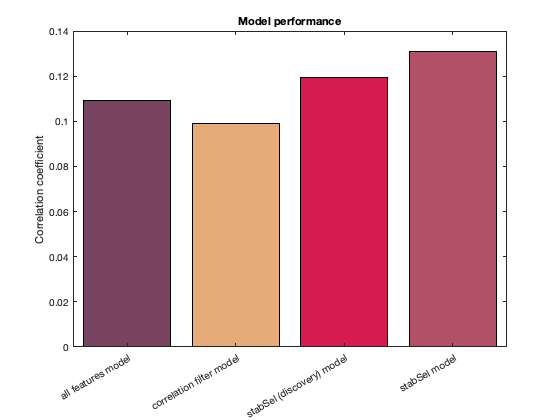

% Create barcharts for performance
b=bar(categorical({'all features model','correlation filter model','stabSel (discovery) model','stabSel model'}),[r2 r3 r4 r1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(4,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
title('Model performance')
ylabel('Correlation coefficient')

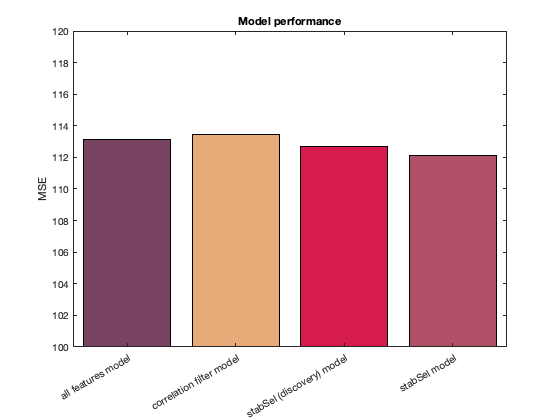

b=bar(categorical({'all features model','correlation filter model','stabSel (discovery) model','stabSel model'}),[mse2 mse3 mse4 mse1],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(4,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
ylim([100 120])
title('Model performance')
ylabel('MSE')

As you can see,the parsimonious model performs better than using all of the data, but not necessarily better than the arbitrary model we started out with. This represents some of the tension between maximizing predictability and the stringent statistical framework for error control in stability selection. However, the parsimonious model has several advantages. It performs nearly as well despite being much less complex, and it ensures that the features it relies on are both highly predictive of our response variable and statistically significantly associated with it. 

# Example 4: More complex feature selection with an elastic net ----------------------------------------------------------------------------

In the last example, we found our parsimonious model (~3 features) to achieve and r of ~0.12 and an mse of 112.68. Can we beat this using more complex methods for feature selection? Here, we will try an elastic net for choosing our features. This involves tuning two parameters during feature selection. To speed up the computational time, we will decrease the number of lambda (regularization) values that we will test, and we will also reduce the number of alpha values that we test (weighting of L1 to L2 norms). This reduction is relative to stabSel defaults, which requires passing in arguments to define lambdas and alphas. In addition, we will switch from subsampling to the more efficient complementary bootstrap method, which converges on stable features more quickly. The bootstrap method also results (theoertically) in less conservative selection. Note, however, that bootstrap stability selection has its own theorum for error control that is less stringent, but has not yet been implemented in stabSel. The standard error control from the original paper should be fine as it will always overestimate the number of false positives. Finally, in this example we will compare feature selection with an elastic net that is based on arbitrary variables to feature selection with error control. **WARNING: THIS EXAMPLE WILL STILL TAKE A SUBSTANTIAL AMOUNT OF TIME TO RUN.**

clear fk % we will index fk now...we will reuse the results in the next example so that we do not have to rerun it again...
for i = 1:c.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c.NumTestSets)])

Working on test set 1 of 8


    trX = X(training(c,i),:); % this determines our training data for fold i
    trY = y(training(c,i)); % this determines our training responses for fold i
    teX = X(test(c,i),:); % this determines our test data for fold i
    teY = y(test(c,i)); % this determines our test responses for fold i. 
    
    % Run stability selection -- *we will save the results so that we do
    % not have to regenerate them in the next example*
    [fk{i},~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','en',...
        'samType','bootstrap','rep',25,'compPars',true,'fdr',0.05,'maxVars',...
        4,'thresh',[],'verbose',false,'ln',50,'alpha',[0.2 0.4 0.6 0.8 1],'fixMax',true); 
    [fk2{i},~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','en',... % note, here we will use the same arbitrary variables we have used in previous examples...
        'samType','bootstrap','rep',25,'compPars',true,'filter',true,'thresh',0.5,...
        'maxVars',round(size(trX,2)/6),'verbose',false,'ln',50,'alpha',[0.2 0.4 0.6 0.8 1],'fixMax',true);
    % Train/test models
    mdl = fitrlinear(trX(:,fk{i}),trY,'Learner','leastsquares'); % train stabSel augmented model
    yhat(test(c,i),1) = predict(mdl,teX(:,fk{i})); % test this model
    mdl = fitrlinear(trX(:,fk2{i}),trY,'Learner','leastsquares'); % train stabSel augmented model
    yhat2(test(c,i),1) = predict(mdl,teX(:,fk2{i})); % test this model
end

% evaluate performance
r5 = corr(y,yhat) 

r5 = 0.1618

mse5 = mean((y-yhat).^2)

mse5 = 110.6366

r6 = corr(y,yhat2) 

r6 = 0.0972

mse6 = mean((y-yhat2).^2)

mse6 = 113.2098

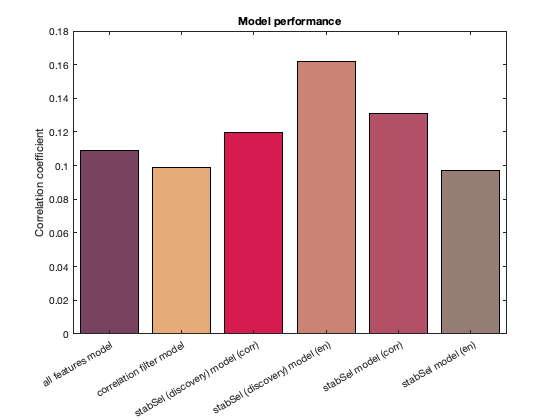

% Create barcharts for performance
b=bar(categorical({'stabSel model (corr)','all features model','correlation filter model','stabSel (discovery) model (corr)','stabSel (discovery) model (en)','stabSel model (en)'}),[r1 r2 r3 r4 r5 r6],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(5,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
b.CData(6,:) = ([150 126 118])/255;
b.CData(4,:) = ([201 132 116])/255;
title('Model performance')
ylabel('Correlation coefficient')

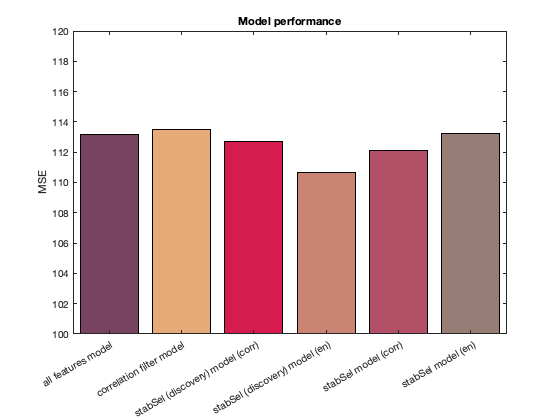

b=bar(categorical({'stabSel model (corr)','all features model','correlation filter model','stabSel (discovery) model (corr)','stabSel (discovery) model (en)','stabSel model (en)'}),[mse1 mse2 mse3 mse4 mse5 mse6],'FaceColor','flat');
b.CData(1,:) = ([119 67 96])/255;
b.CData(5,:) = ([178 80 104])/255;
b.CData(2,:) = ([231 171 121])/255;
b.CData(3,:) = ([214 28 78])/255;
b.CData(6,:) = ([150 126 118])/255;
b.CData(4,:) = ([201 132 116])/255;
ylim([100 120])
title('Model performance')
ylabel('MSE')

Looks like we can! When running this, I got a correlation value of 0.16 (c.f. 0.12 for correlation and 0.109 using all features) and a slightly lower MSE (110.9 vs 112.5 vs 113.1). Note that we would likely get better results if : i) we increased the range of parameters that we test closer to default values because we might be missing a parameter that gives us even more stable results, and ii) tried to build a more complex model AFTER feature selection. One remaining issue is that stability selection returned just a single feature for each fold, so while our model performs better, it's arguably too simple. We will address this in the next example.

# Example 5: Building a more complex model and a comparison to nested feature selection with LASSO --------------------------

In the examples above we were relying on a specific kind of linear regression to make predictions--ridge regression. But would our performance improve if we try to fit a more compelx model to the data after perfroming stability selection? Below, we will try to make predictions using a linear SVM. To minimize computational time we will not be tuning our hyperparameters. The reason we relied on fitrlinear in the examples above is because it efficiently fits models in high-dimensional spaces. Given the large amount of samples in our dataset, fitrlinear SIGNIFICANTLY reduces the run time of our pipeline. Consequently, when we use SVM below, we will use it on just 2% of the data we started out with. If you would like to appreciate how much longer training a SVM takes on the full dataset, you can alter the code below to use all of the data.

One additional experiment we will perform below is to determine whether stability selection works better than simply using LASSO with cross-validation. That is, we will create a nested cross-validation scheme in which we use LASSO in the inner folds to estimate how many features of our data to keep. For stability selection, here, we will use a single false positive as our thresholds, which gives us a relatively low per-comparison ratio of 1/90.

% Let's take the first 2% of samples that we "collected"
X2 = X(1:1000,:);
y2 = y(1:1000);
c2 = cvpartition(length(y2),'Kfold',8); % we need to form new folds for testing our model. That's because we now have fewer sample to train/test
for i = 1:c2.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c2.NumTestSets)])
    trX = X2(training(c2,i),:); % this determines our training data for fold i
    trY = y2(training(c2,i)); % this determines our training responses for fold i
    teX = X2(test(c2,i),:); % this determines our test data for fold i
    teY = y2(test(c2,i)); % this determines our test responses for fold i. 
    
    % Run stability selection 
%     [fk{i},fscmx,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','en',...
%         'samType','bootstrap','rep',50,'compPars',true,'numFalsePos',1,'maxVars',15,'thresh',...
%         [],'verbose',false,'ln',50,'alpha',[0.2 0.4 0.6 0.8 1],'fixMax',true);
%     
%     % run lasso-based feature selection
%     disp('Performing feature selection using lasso')
%     [B,FitInfo] = lasso(trX,trY,'CV',4); % run lasso using 4 inner folds generated from training data ONLY
%     idxLambda1SE = FitInfo.Index1SE; % the 1 standard error rule selects the highest regularization parameter within 1 standard error of the regularization parameter that produces the lowest error (error is averaged across folds for each lambda)
%     coef = B(:,idxLambda1SE); % extract coefficients with the corresponding 1SE lambda 
%     fkl{i} = find(coef > 0); % identify non-zero coefficients as surviving features 

    % Train/test models
    disp('Training/testing models')
    mdl = fitrsvm(trX(:,fk{i}),trY,'OptimizeHyperparameters',{'BoxConstraint'},'Standardize','on',...
        'HyperparameterOptimizationOptions',struct('MaxObjectiveEvaluations',...
    15,'Verbose',0,'ShowPlots',false));
    yhatt(test(c2,i),1) = predict(mdl,teX(:,fk{i})); % test model (stabSel feature selection)
    mdl = fitrsvm(trX(:,fkl{i}),trY,'OptimizeHyperparameters',{'BoxConstraint'},'Standardize','on',...
        'HyperparameterOptimizationOptions',struct('MaxObjectiveEvaluations',...
    15,'Verbose',0,'ShowPlots',false));
end

Working on test set 1 of 8


Training/testing models


Working on test set 2 of 8


Training/testing models


Working on test set 3 of 8


Training/testing models


Working on test set 4 of 8


Training/testing models


Working on test set 5 of 8


Training/testing models


Working on test set 6 of 8


Training/testing models


Working on test set 7 of 8


Training/testing models


Working on test set 8 of 8


Training/testing models


%evaluate performance
r7 = corr(y2,yhatt) % stabSel model

r7 = 0.3758

mse7 = mean((y2-yhatt).^2)

mse7 = 165.7347

r8 = corr(y2,yhatt2) % lasso feature selection model

r8 = 0.2823

mse8 = mean((y2-yhatt2).^2)

mse8 = 175.6962

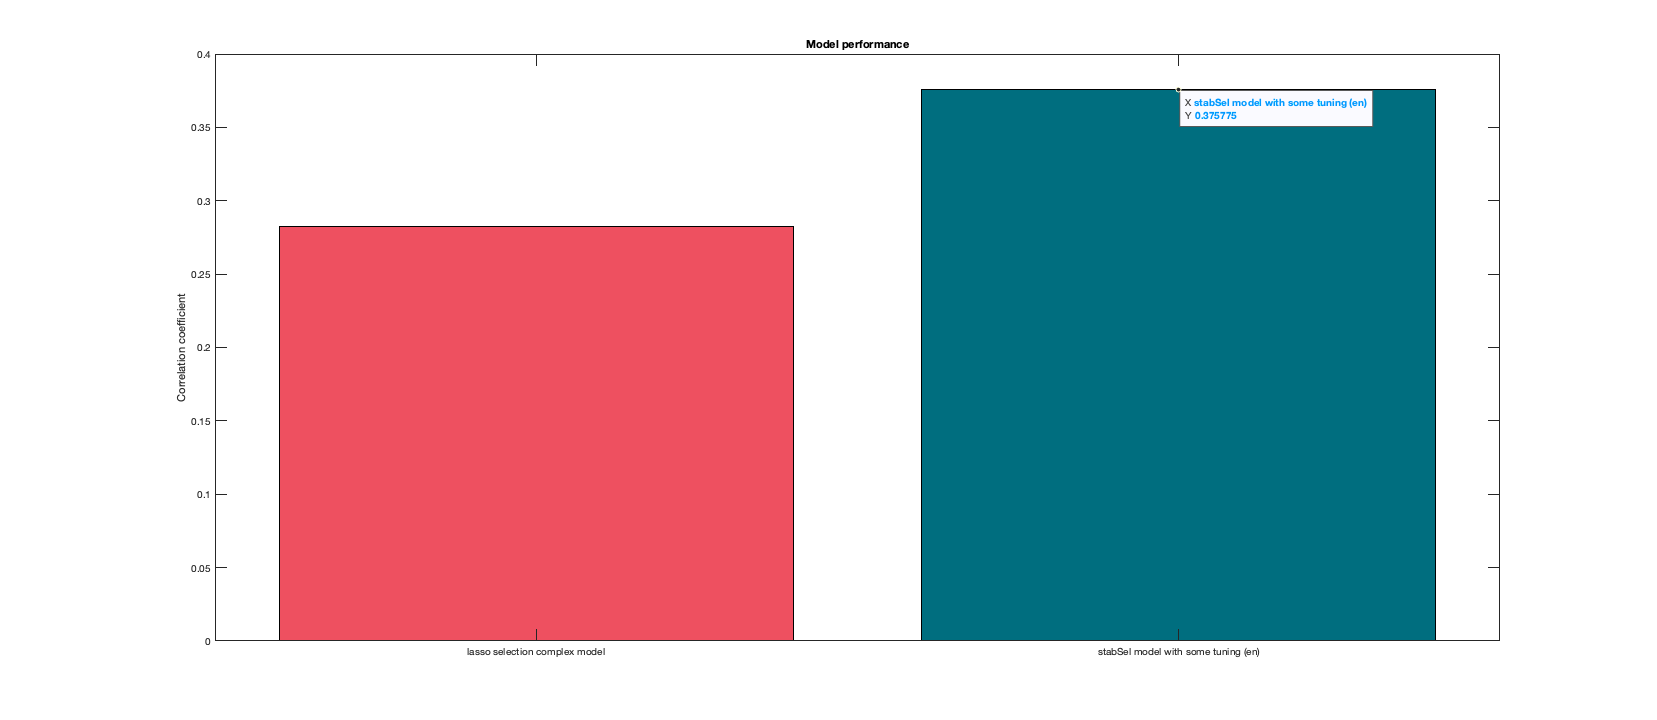

% Create barcharts for performance
b=bar(categorical({'stabSel model with some tuning (en)','lasso selection complex model'}),[r7 r8],'FaceColor','flat');
b.CData(1,:) = ([238 80 96])/255;
b.CData(2,:) = ([0 110 127])/255;
title('Model performance')
ylabel('Correlation coefficient')

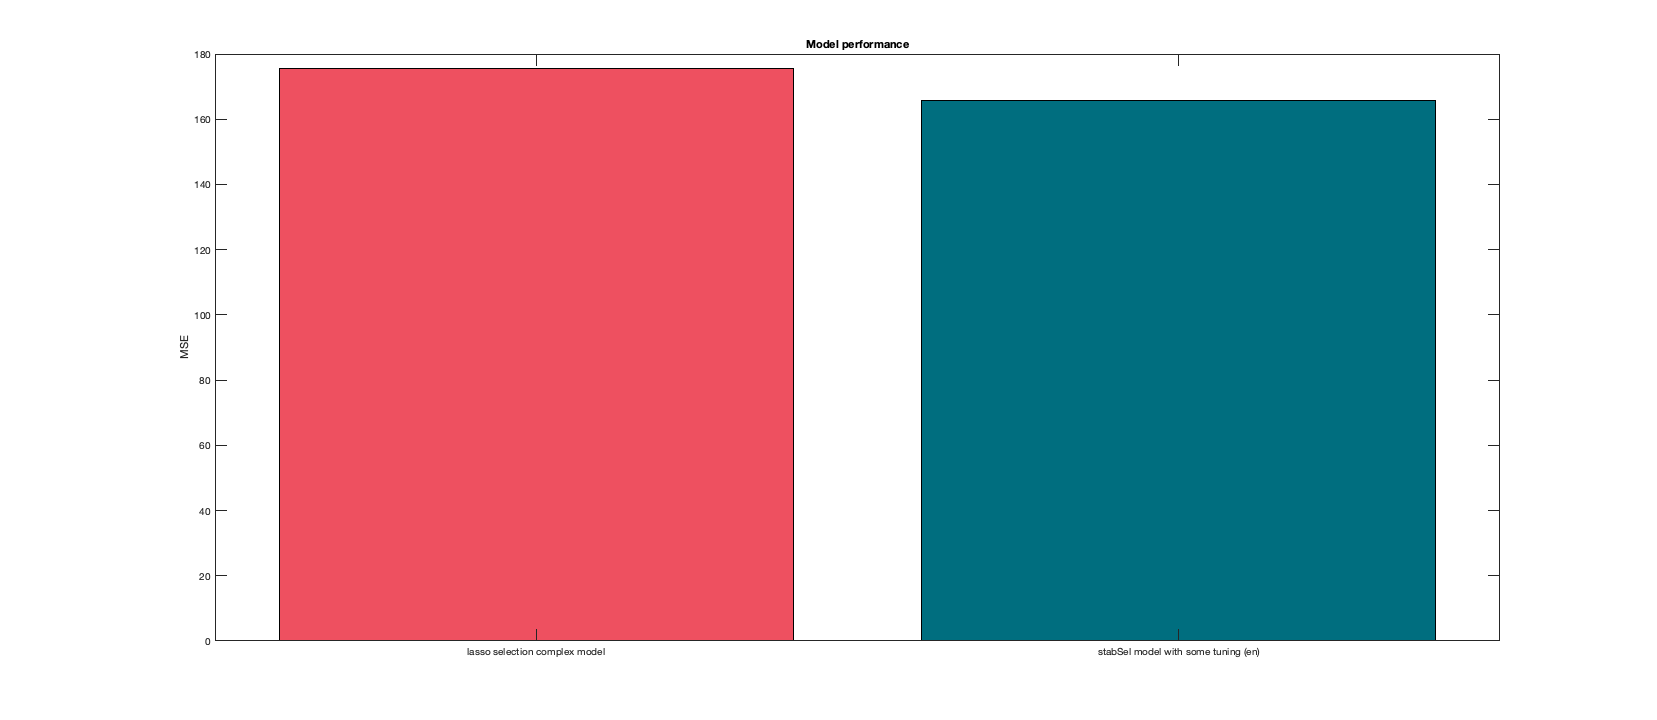

b=bar(categorical({'stabSel model with some tuning (en)','lasso selection complex model'}),[mse7 mse8],'FaceColor','flat');
b.CData(1,:) = ([238 80 96])/255;
b.CData(2,:) = ([0 110 127])/255;
title('Model performance')
ylabel('MSE')

As you can see, the stabSel feature selection model performs much better than the lasso feature selection model (r = 0.37 1in r7 vs 0.28 in r8). This is corroberated by MSE. Moreover, building a more complex model after feature selection gives much better results! 

# Example 6: Feature selection with adaptive lasso and adaptive elastic net ------------------------------------------------------------

stabSel can implement adaptive LASSO and adaptive EN, where we initialize EN or lasso with rdige regression weights (like a  warm-start). Adaptive LASSO improves the consistency of LASSO. It provides more consistant variable selection by regularization and is less sensitive to noise so its weights are more precise (e.g. lasso lacks "oracle" properties so we would not be necessarily perform as well if the correct model was known ahead of time). Adaptive lasso improves lasso--but can still encounter difficulties--when there are colinearities in the data or strong noise. For this reason, the adaptive elastic net has been proposed. Wrapping stability selection around the adaptive elastic net gives us the benefit of being able to test how well adaptive lasso/EN handles collinearities and noise. In practice, I often rely on the elastic net alone because the adaptive elastic net adds substantial computational time at the moment. Moreover, I often find that adaptive lasso improves model performance over lasso but NOT inside the stability selection framework, where often the elastic net is better. I'm not quite sure why this is the case, but it may be connected to the fact that adaptive lasso/EN typically produces much sparser stable sets. In any case, if you did want to try adaptive LASSO/EN on your data, here is how you might set things up. Stay tuned for improvements to make it more efficient in future updates!

for i = 1:c2.NumTestSets 
    % Get train/test splits
    disp(['Working on test set ' num2str(i) ' of ' num2str(c2.NumTestSets)])
    trX = X2(training(c2,i),:); % this determines our training data for fold i
    trY = y2(training(c2,i)); % this determines our training responses for fold i
    teX = X2(test(c2,i),:); % this determines our test data for fold i
    teY = y2(test(c2,i)); % this determines our test responses for fold i. 
    
    % Run stability selection
    [fk{i},~,~,~,~,~,~,~,~,~,~,~,~,~] = stabSel(trX,trY,'selAlgo','lasso','adaptive',true,... % the 'adaptive' argument controls whether lasso or en as specified for 'selAlgo' is adaptive
        'samType','bootstrap','rep',50,'compPars',true,'fwer',0.05,'maxVars',4,'thresh',[],'verbose',false,'ln',50,'parallel',true); % when doing adaptive lasso/en, try to enable parallelization to save some time
    
    % Train/test models
    mdl = fitrsvm(trX(:,fk{i}),trY);
    yhatt(test(c2,i),1) = predict(mdl,teX(:,fk{i})); 
end

% evaluate performance
r9 = corr(y2,yhatt) 
mse9 = mean((y2-yhatt).^2)

# Tuning the number of variables in the stable set for maximal model generalizability ------------------------------------------------

You can think of the parameters stabSel requires to function (either maxVars or thresh) as a parameter that you can tune inside your cross validation scheme. This may be advantageous because controling FWER can be at odds with maximizing the generalizability of your model. Sure, maybe these few features stabSel returns are very unlikely to be false positives, but including some features that have a greater likelihood of being false positives might improve the model's ability to generalize to new data (e.g., because they are not false positives). Nothing is stopping us from creating a nested CV scheme where in the inner loop we try multiple different parameters (e.g., different maxVars), then select the parameter that gives us the best generalizability. We could even use the inner loop to continue tuning our final model built up using the stable set of features returned by stabSel. 

% EXAMPLE CODE FORTHCOMING

# Citations and final notes-------------------------------------------------------------------------------------------------------------------------------

As a final note, in hindsight, the dataset I have selected here is not optimal for feature selection. I mentioned this previously to be the case because it's high dimensional in the n >> p sense instead of p >> n. However, there is another reason it is not well suited to the task at hand...it has actually been preprocessed (quite well) for us already! The variables we have here are the outputs from a components analysis. While methods like PCA can still produce noise components, they are often robust (dimensionality reduction is an arguably worse alternative to feature selection), and there are no such components here. Evidence for this comes from the fact that you will get remarkably high performance without feature selection at all, for example, by running a simple OLS linear regression model in our 8-fold cross validation scheme (r = ~0.42). If you do try to tune the SVR model in example 4, you will see that you can approach the same level of performance with stability selection, suggesting that you can still use feature selection to build a model that is just as succesful, but substantially simpler. In most application settings where you're not trying to wrangle your features using multiple opposing methods, stability selection will not just simplify your model but also make it better (provided you spend some time properly implementing it). 

For original method and details of stability selection, see: Meinshausen, N., & Bühlmann, P. (2010). Stability selection. Journal of the Royal Statistical Society: Series B (Statistical Methodology), 72(4), 417-473.

For complementary pairs, see: Shah, R. D., & Samworth, R. J. (2013).Variable selection with error control: another look at stability selection. Journal of the Royal Statistical Society: Series B(Statistical Methodology), 75(1), 55-80.

For adaptive EN/lasso: Zou, H., & Zhang, H. H. (2009). On the adaptive elastic-net with a diverging number of parameters. Annals of statistics, 37(4), 1733.). 